set(groot, 'defaultAxesTickLabelInterpreter',"latex");
set(groot, 'defaultLegendInterpreter', "latex");
set(groot, 'defaulttextinterpreter',"latex");

# SID Methods Compared to Original Time Series Data

Script performs the following

- Load DEAP data for a single subject

- Selects a single trial for that subject

- Visualize the original (detrended) data

- Run 4 output only system ID algorithms to determine A,C matricies 

- Compare results to original time series

## Prepare Dataset

s02=load('s09.mat');
subject=09;
basename='S015E';
extension='.png';
trial=1;

Y=s02.data(trial,[3,4,31,27,28],:); %selecting the F row, across the top of the head


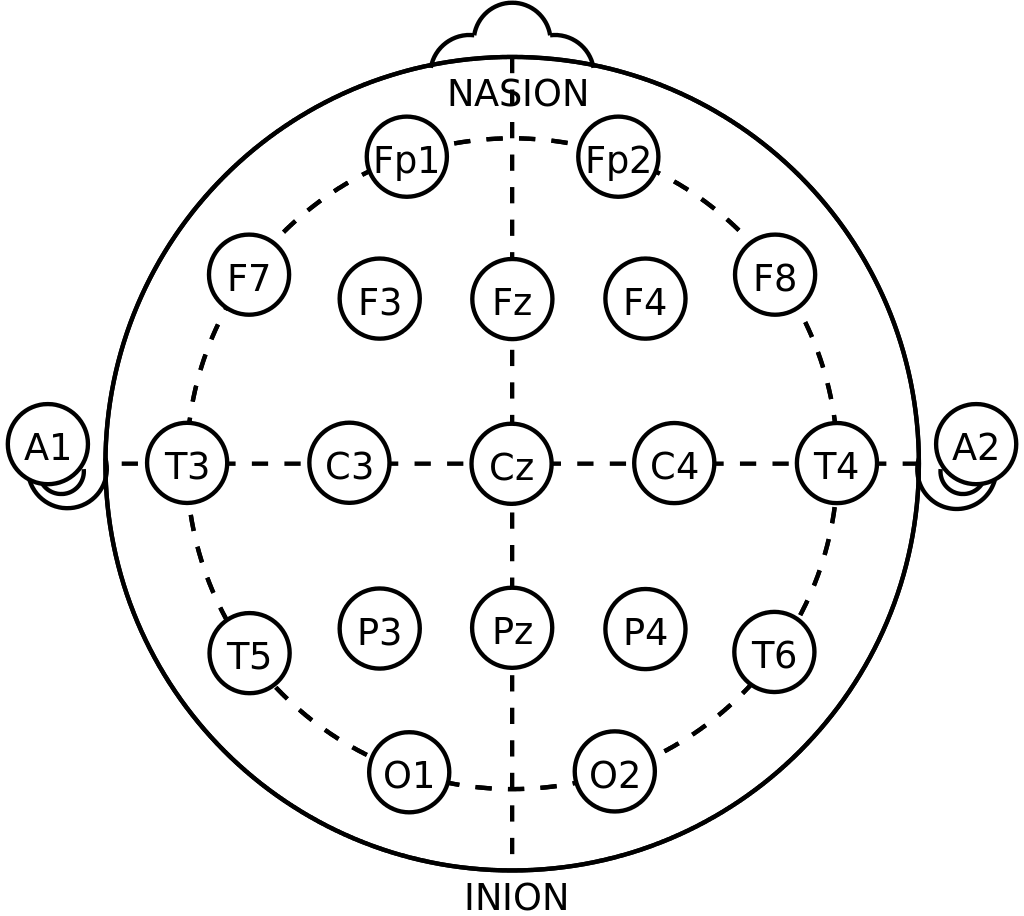

Y=squeeze(Y);
t = linspace(0,63,length(Y));
fs=128;
T=1/fs;

## Visualize Dataset

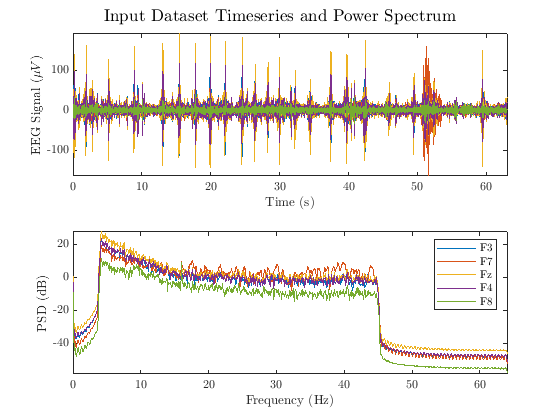

[Syy,freqs] = pwelch(Y',[],[],[],fs); % obtain estimates of the output power spectrums
clf
subplot(2,1,1)
plot(t,Y)
xlabel('Time (s)')
ylabel('EEG Signal ($\mu V$)', "Interpreter","latex")
sgtitle('Input Dataset Timeseries and Power Spectrum')
axis tight
subplot(2,1,2)
plot(freqs,10*log10(Syy))
xlabel('Frequency (Hz)')
ylabel('PSD (dB)')
legend('F3','F7','Fz','F4','F8')
axis tight

## Run Output Only Algorithms

Includes traditional OMA, the later developed OMA-data, the Matlab default n4sid, and NeXT-ERA. 

### 1. OMA

[1] "System Identification Methods for (Operational) Modal Analysis: Review and Comparison" by Edwin Reynders in Archives of Computational Methods in Engineering, Vol. 19, No. 1, doi:10.1007/s11831-012-9069-x

Assumes outputs are corrupted by additive sensor noise, and **inputs are stochastic, unobserved.**

order = 25;
s = 2*order;

[A_cov,C_cov,G_cov,R0_cov] = ssicov(Y,order,s);

SSI-cov status:
  forming block Hankel matrix...
  performing singular value decomposition...
  generating system matrices A,C,G for 25 model orders...
SSI-cov finished.


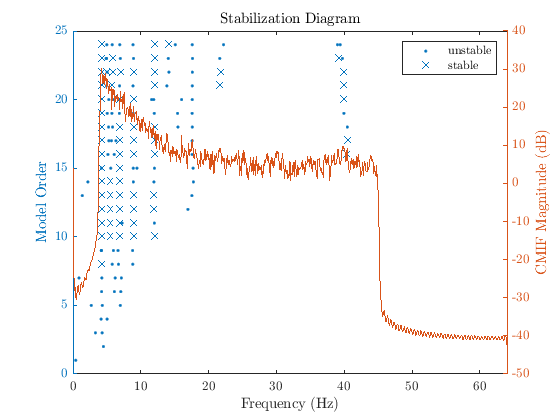


err = [5e-3,0.1,0.98];
[IDs_cov] = plotstab(A_cov,C_cov,Y,T,[],err);

Classify a pole as stable in freq if its natural freq changes by less than 0.5% as the model order increases. Classify pole as stable if damping ratio changes by less than 10% as model order increases. Arbitrary, and based on guess and check.

[fn_cov,zeta_cov,Phi_cov] = modalparams(A_cov,C_cov,T);
opt_order=12; %purely just cause here, seems to have the most modes
eig(A_cov{opt_order})

ans =    0.6236 + 0.6790i
   0.6236 - 0.6790i
   0.8020 + 0.5296i
   0.8020 - 0.5296i
   0.9659 + 0.2014i
   0.9659 - 0.2014i
   0.8988 + 0.2420i
   0.8988 - 0.2420i
   0.9275 + 0.3222i
   0.9275 - 0.3222i


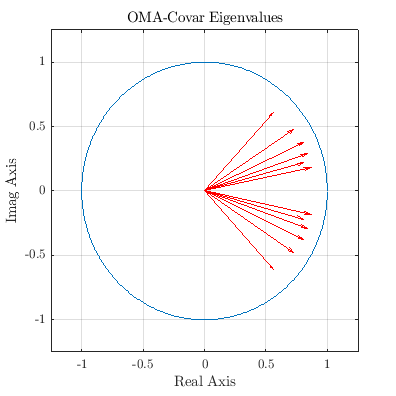

real_part_OMA=real(eig(A_cov{opt_order}));
imag_part_OMA=imag(eig(A_cov{opt_order}));
figure
set(gcf,'units','points','position',[25,25,300,300])
circle(0,0,1)
hold on

for i=1:12
    quiver (0,0,real_part_OMA(i),imag_part_OMA(i), 'r')
    hold all
end
xlim([-1.25 1.25])
ylim([-1.25 1.25])
title('OMA-Covar Eigenvalues')
xlabel('Real Axis')
ylabel('Imag Axis')
grid on

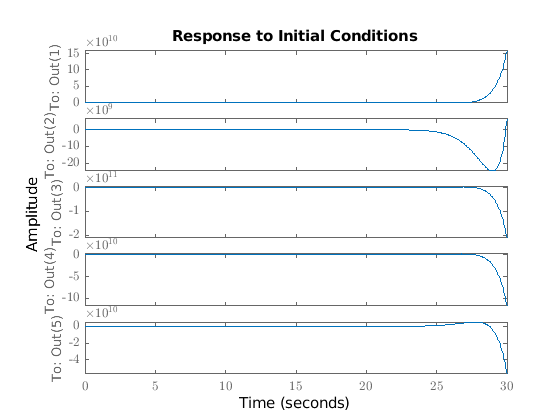

sys_cov=ss(A_cov{opt_order},[],C_cov{opt_order},0);
figure
initial(sys_cov,[0 0 0 0 0 0 0 0.1 0 0 0 0])

### 2. OMA Data

Same basic principles as OMA, but with less assumptions on the nature of the input. 

Assumes no input, free vibration under initial conditions

[2] "Subspace Identification for Linear Systems" by Peter van Overschee and Bart de Moor, doi:10.1007/978-1-4613-0465-4

[A_data,C_data,G_data,R0_data] = ssidata(Y,order,s);

SSI-data status:
  forming shifted data matrix...
  projecting raw data...
  performing singular value decomposition...
  generating system matrices A,C,G for 25 model orders...
SSI-data finished.


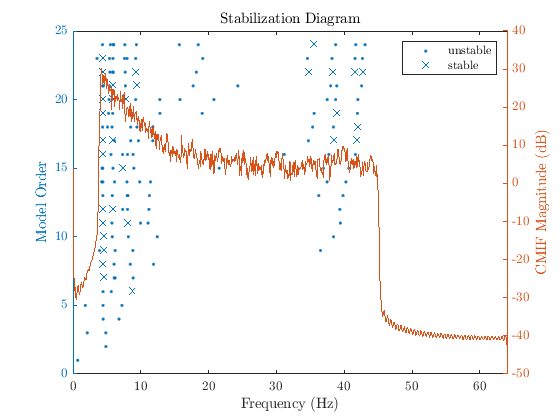

[fn_data,zeta_data,Phi_data] = modalparams(A_data,C_data,T);
[IDs_data] = plotstab(A_data,C_data,Y,T,[],err);

eig(A_data{opt_order})

ans =   -0.3317 + 0.8818i
  -0.3317 - 0.8818i
  -0.1519 + 0.0000i
   0.6889 + 0.3684i
   0.6889 - 0.3684i
   0.8605 + 0.3516i
   0.8605 - 0.3516i
   0.9698 + 0.2130i
   0.9698 - 0.2130i
   0.9355 + 0.2714i


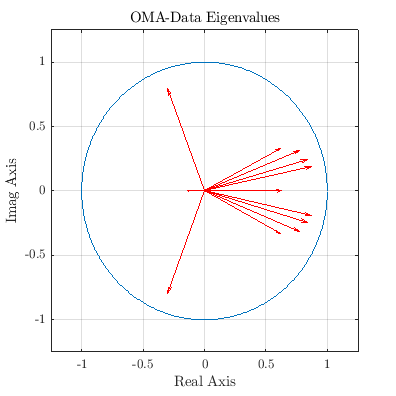

real_part_data=real(eig(A_data{opt_order}));
imag_part_data=imag(eig(A_data{opt_order}));
figure
set(gcf,'units','points','position',[25,25,300,300])
circle(0,0,1)
hold on

for i=1:12
    quiver (0,0,real_part_data(i),imag_part_data(i), 'r')
    hold all
end
xlim([-1.25 1.25])
ylim([-1.25 1.25])
title('OMA-Data Eigenvalues')
xlabel('Real Axis')
ylabel('Imag Axis')
grid on

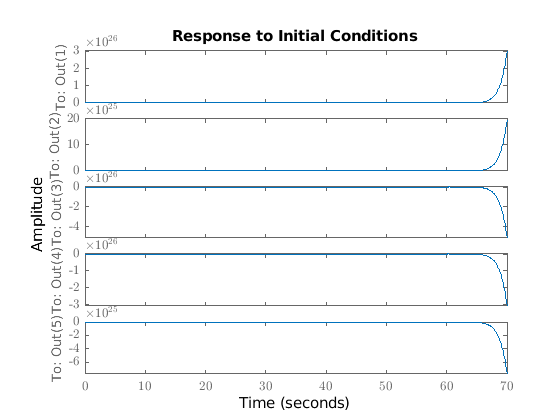

sys_data=ss(A_data{opt_order},[],C_data{opt_order},0);
figure
initial(sys_data,[0 0 0 0 0 0 0 0.1 0 0 0 0])

### 3. n4sid

This is the Matlab default system id algorithm. It generally shows better results with B data, which we don't have. We'll see this makes the results crappy. 

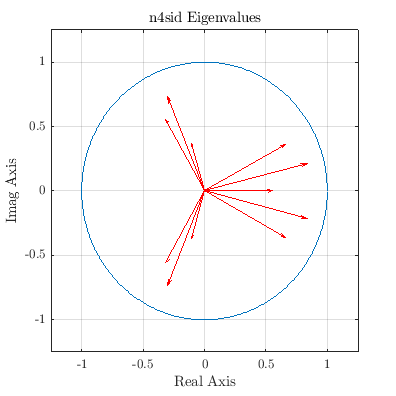

data = iddata(Y',[],T);
sys = n4sid(data,12);
[A_n4,~,C_n4,~] = ssdata(sys);
real_part_n4=real(eig(A_n4));
imag_part_n4=imag(eig(A_n4));
figure
set(gcf,'units','points','position',[25,25,300,300])
circle(0,0,1)
hold on

for i=1:12
    quiver (0,0,real_part_n4(i),imag_part_n4(i), 'r')
    hold all
end
xlim([-1.25 1.25])
ylim([-1.25 1.25])
title('n4sid Eigenvalues')
xlabel('Real Axis')
ylabel('Imag Axis')
grid on

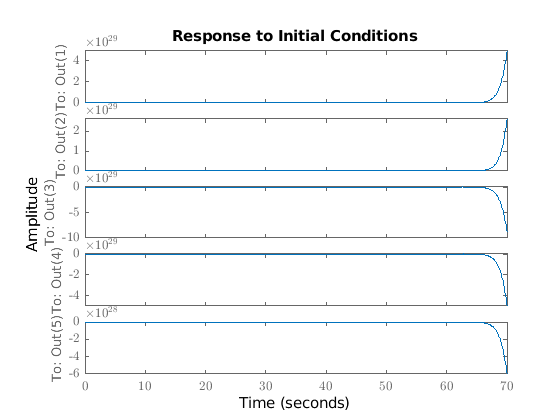

sys_n4=ss(A_n4,[],C_n4,0);
figure
initial(sys_n4,[0 0 0 0 0 0 0 0.1 0 0 0 0])

### 4. NeXT-ERA

[3] R. Pappa, K. Elliott, and A. Schenk, A consistent-mode indicator for the eigensystem realization algorithm, Journal of Guidance Control and Dynamics (1993), 1993.

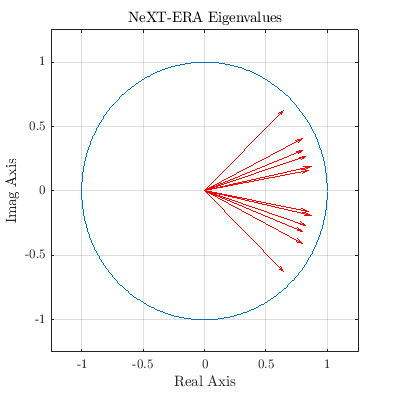

[NeXT]=NExTFERA(Y,5,2000,4,0.1,fs,800,200,12,10,1);
real_part_NeXT=real(eig(NeXT.Matrices.A));
imag_part_NeXT=imag(eig(NeXT.Matrices.A));
figure
set(gcf,'units','points','position',[25,25,300,300])
circle(0,0,1)
hold on

for i=1:12
    quiver (0,0,real_part_NeXT(i),imag_part_NeXT(i), 'r')
    hold all
end
xlim([-1.25 1.25])
ylim([-1.25 1.25])
title('NeXT-ERA Eigenvalues')
xlabel('Real Axis')
ylabel('Imag Axis')
grid on

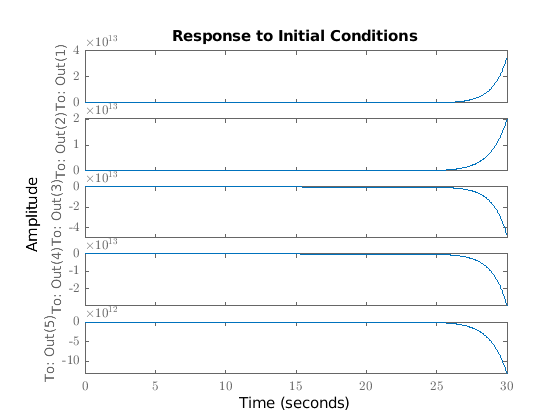

sys_NeXT=ss(NeXT.Matrices.A,[],NeXT.Matrices.C,0);
figure
initial(sys_NeXT,[0 0 0 0 0 0 0 0 0 0 0 0.2])

## Working Questions:

- A matrices aren't stable. Lots of spikes in the original data drive this. (looks like unstable jet plane inputs to me)

- Difficult to select proper system order (generally true in the data, but hard to compare since I can't line up impulse to impulse)

- Generates a new A and C matrix for every subject and emotion. (Average the A's? Do other fields have non-deterministic ss models?)

- Wild Variance from subject to subject

Technical details: [Link](https://link.springer.com/article/10.1007/s11831-012-9069-x)